%PID CONTROL CENTRALIZADO
clc; close all; clear all;
 m1 = 0.75;
 m2 = 0.5;
 k1 = 100;
 k2 = 100;
 p1 = 80;
 p2 = 50;
A = [0 0 1 0;0 0 0 1;(-k1-k2)/m1 k2/m1 (-p1-p2)/m1 p2/m1; k2/m2 -k2/m2 p2/m2 -p2/m2 ]

A =          0         0    1.0000         0
         0         0         0    1.0000
 -266.6667  133.3333 -173.3333   66.6667
  200.0000 -200.0000  100.0000 -100.0000


B = [0 0; 0 0; 1/m1 0 ; 0 1/m2]

B =          0         0
         0         0
    1.3333         0
         0    2.0000


C = [eye(2), zeros(2)];
D = [zeros(2)];

% estabilidad
eig(A)

ans =  -224.4072
   -2.0432
   -1.2752
  -45.6077


Gss = ss(A,B,C,D)

Gss =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3  -266.7   133.3  -173.3   66.67
   x4     200    -200     100    -100
 
  B = 
          u1     u2
   x1      0      0
   x2      0      0
   x3  1.333      0
   x4      0      2
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


G = tf(Gss);
pole(G)

ans =  -224.4072
  -45.6077
   -2.0432
   -1.2752
 -224.4072
  -45.6077
   -2.0432
   -1.2752


s = tf('s');

% pidtune()
% 
% C(1,1) = kp11 +  kd11*s + ki11/s
% C(1,1) = kp12 +  kd12*s + ki12/s
% C(1,1) = kp21 +  kd21*s + ki21/s
% C(1,1) = kp22 +  kd22*s + ki22/s

Glc = feedback(G,eye(2))

Glc =
 
  From input 1 to output...
                  1.333 s^6 + 497.8 s^5 + 5.156e04 s^4 + 1.604e06 s^3 + 7.656e06 s^2 + 1.289e07 s + 7.182e06
   1:  -----------------------------------------------------------------------------------------------------------------
       s^8 + 546.7 s^7 + 9.698e04 s^6 + 6.157e06 s^5 + 1.431e08 s^4 + 7.922e08 s^3 + 1.821e09 s^2 + 1.89e09 s + 7.325e08
 
                         133.3 s^5 + 3.671e04 s^4 + 1.557e06 s^3 + 7.591e06 s^2 + 1.28e07 s + 7.111e06
   2:  -----------------------------------------------------------------------------------------------------------------
       s^8 + 546.7 s^7 + 9.698e04 s^6 + 6.157e06 s^5 + 1.431e08 s^4 + 7.922e08 s^3 + 1.821e09 s^2 + 1.89e09 s + 7.325e08
 
  From input 2 to output...
                         133.3 s^5 + 3.671e04 s^4 + 1.557e06 s^3 + 7.591e06 s^2 + 1.28e07 s + 7.111e06
   1:  -----------------------------------------------------------------------------------------------------------------
       s^8 +

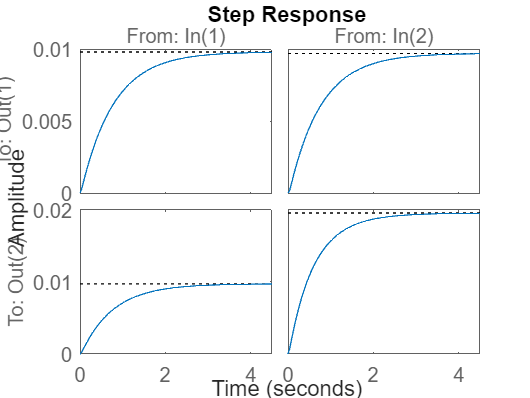

step(Glc)